# M E 325 Exam 1 Problem 1

### Group 6

#### Parker Wilson, Preston Witte, Mike Lawlor, Justin Merkel

A 0.004 inch edge crack is found in a machine component fabricated from amaterial with the following properties:

Sut = 185 kpsi

Sy = 170 kpsi

KIC = 73 kpsi √in

C = 3.8 ×10−11 incylcekpsi √in

m = 3

The part has a cross-section that is 14 inch wide and 12 inch thick and its lengthis 2.00 inches. A normal force varies from a value of 500 lb to 0 lbs and abending moment is applied that varies between a maximum value of 1200 in-lb and a minimum value of 0 in-lb. Both loads result in tensile stresses that causemode I loading. The geometry correction factors for both the axial force and the bending moment can be assumed to be β = 1.07

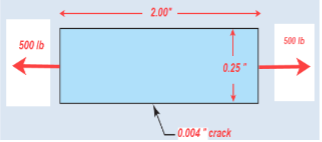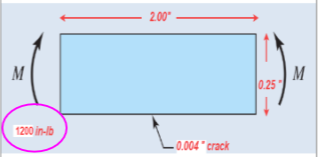

Determine:

1. af, the critical crack length

2. N, the number of cycles, N, until the critical crack length is reached.

3. nyield, the factor of safety against yielding

4. σc, the critical stress based on LEFM analysis

Submit:

`•`Results generated by the software of your team’s choice.

`•`Along with numerical results, include the symbolic equations used to gen-

erate them

Clearing all values from the command window.

clc
clear all

Inputting the given variables and parameters.

Sy = 170;
Sut = 185;
c = 3.8*10^-11;
m = 3;
Width = 0.25;
Length=2;
Thickness = 0.5;
Moment = 1200;
Tension = 500;
Kic = 73;
Beta=1.07;
Area=Width*Thickness;
a=0.004;

Calculating the Moment of Inertia

I1 = (Length*Width^3)/12;

Stress in Kpsi for Moment and Tension Loading

Sigma = (((Moment*Width/2)/I1)+(Tension/Area))/1000;  

From the chart beta was found to be 1.07 for our ratio

af = (1/pi)*(Kic/(1.07*Sigma))^2;

Because of the parameters of the problem and af exceeds 0.25, we will use 0.25 in place of it to calculate the cycles to failure.

Nf =(-1/(Beta*Sigma*sqrt(pi*0.25))^m+(1/(Beta*Sigma*sqrt(pi*a))^m))/c;

Factor of Safety Due to Yielding

FS_Yield=Sy/Sigma;

Factor of Safety including crack length

Ki=1.07*Sigma*sqrt(pi*a);
FS_Crack=Kic/Ki;

Calculating Critical Stress

Critical_Stress=FS_Crack*Sigma;

Outputting Desired Values/Answers

W= sprintf('Critical Crack Length = %s in',af);
disp(W)

Critical Crack Length = 3.904513e-01 in


X = sprintf('Number of Cycles to Critical Crack Length = %s',Nf);
disp(X);

Number of Cycles to Critical Crack Length = 6.510709e+07


Y= sprintf('Factor Of Safety Against Yielding = %s ',FS_Yield);
disp(Y)

Factor Of Safety Against Yielding = 2.759740e+00 


Z= sprintf('Critical Stress = %s Kpsi',Critical_Stress);
disp(Z)

Critical Stress = 6.086031e+02 Kpsi
